***1 a)***

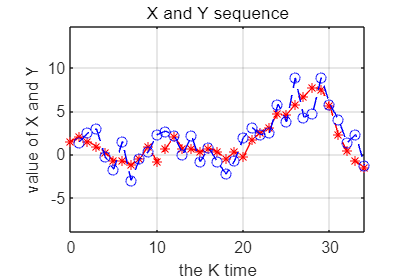

%set the parameters 
x_0=2;
P_0=8;
Q=1.5;
R=3;
A=1;
H=1;
N=34;
%use functions to get sequences
X_s=genLinearStateSequence(x_0, P_0, A, Q, N);
Y_s=genLinearMeasurementSequence(X_s,H,R);

figure('Position',[300 300 600 400]);
h1 = plot(0:34,X_s,'r--*');
hold on
axis equal
h2 = plot(1:34,Y_s,'b--o');
hold off
grid on 
xlabel('the K time') % Set x-axis label
ylabel('value of X and Y') % Set y-axis label
title('X and Y sequence')

***1 b)***

% Use the KalmanFilter to get X,P estimate
[X_est, P_e] = kalmanFilter(Y_s,x_0, P_0, A, Q, H, R);

%change the sigma^2 P_e into a two dimension array so we cancalculate later
P_est =[];
for i =1:length(X_est)
    P_est =[P_est P_e(:,:,i)];
end
%P_est=reshape(P_e,1,34);
%get 3 sigma level
Sigma3  = X_est+3*sqrt(P_est);
Sigma_3 = X_est-3*sqrt(P_est);
%get correct states
X_t = genLinearStateSequence(x_0, P_0, A, 0, N)

X_t =    -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375   -0.3375


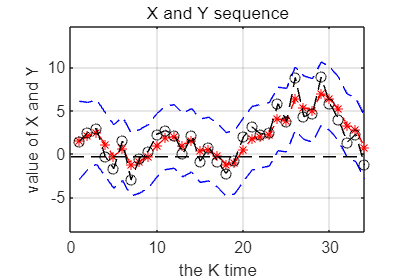



figure('Position',[300 300 600 400]);
plot(1:34,X_est,'r--*');
hold on
axis equal
plot(1:34,Sigma3,'b--');
hold on
plot(1:34,Sigma_3,'b--');
hold on
plot(1:34, Y_s, 'k--o');
hold on
plot(0:34, X_t, 'k--');
grid on 
xlabel('the K time')
ylabel('value of X and Y')  
title('X and Y sequence')

***The functions that might be used in the tasks***

function X = genLinearStateSequence(x_0, P_0, A, Q, N)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
mu=(mvnrnd(x_0,P_0))';

X=[mu];
for i= 1:N
    mu=A*mu+(mvnrnd(zeros(length(Q),1),Q))';
    X=[X mu];
    
end
end


function Y = genLinearMeasurementSequence(X, H, R)
%GENLINEARMEASUREMENTSEQUENCE generates a sequence of observations of the state 
% sequence X using a linear measurement model. Measurement noise is assumed to be 
% zero mean and Gaussian.
%
%Input:
%   X           [n x N+1] State vector sequence. The k:th state vector is X(:,k+1)
%   H           [m x n] Measurement matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% your code here
Y=[];
for i=2:length(X)
    y=H*X(:,i)+(mvnrnd(zeros(length(R),1),R))';
    Y=[Y y];
end
end

function [X, P] = kalmanFilter(Y, x_0, P_0, A, Q, H, R)
%KALMANFILTER Filters measurements sequence Y using a Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   A           [n x n] State transition matrix
%   Q           [n x n] Process noise covariance
%   H           [m x n] Measurement model matrix
%   R           [m x m] Measurement noise covariance
%
%Output:
%   x           [n x N] Estimated state vector sequence
%   P           [n x n x N] Filter error convariance
%

%% Parameters
N = size(Y,2);

n = length(x_0);
m = size(Y,1);

%% Data allocation
X = zeros(n,N);
P = zeros(n,n,N);

x_up=x_0;
P_up=P_0;

for i=1:N
[x_pre, P_pre] = linearPrediction(x_up, P_up, A, Q);
[x_up, P_up] = linearUpdate(x_pre, P_pre, Y(:,i), H, R);

X(:,i)=x_up;
P(:,:,i)=P_up;
end
end
function [x, P] = linearPrediction(x, P, A, Q)
x=A*x;
P=A*P*A'+Q;
end
function [x, P] = linearUpdate(x, P, y, H, R)
v=y-H*x;
s=H*P*H'+R;
k=P*H'*inv(s);

x=x+k*v;
P=P-k*s*k';
end
